# Span a Table Entry Across Rows and Columns

These examples show how to make a table entry span rows and columns.

## Informal Table

This example shows how to use row and column spanning in a DOM informal table object to create the following table.

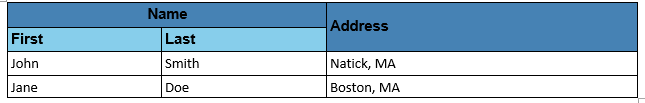

An informal table is a table that does not include pre-defined head, body, and foot sections. However, you can format the first few rows of an informal table as a header as this example shows.

Import the DOM package so you do not have to use long, fully qualified class names.

import mlreportgen.dom.*

Set up the document and add a heading to describe the table.

% To create a PDF report, change the output type from "docx" to "pdf". 
% To create an HTML report, change "docx" to "html" or "html-file" for
% a multifile or single-file report, respectively.
rpt = Document('myReport','docx');

h = Heading(1, 'Multiple Row and Column Table Entries Using an Informal Table');
h.Style = [h.Style {HAlign('center')}];
append(rpt, h);

Create cell arrays for the styles to be used by the different document components. The containing table spans the width of the page and has solid lines separating the entries. The main header is steel blue, and then sub-header is a lighter sky blue.

tableStyle = {Width('100%'), Border('solid'), ColSep('solid'), RowSep('solid')};
mainHeaderRowStyle = {VAlign('middle'), InnerMargin('2pt', '2pt', '2pt', '2pt'), ...
    BackgroundColor('steelblue')};
mainHeaderTextStyle = {Bold, OuterMargin('0pt', '0pt', '0pt', '0pt'), FontFamily('Arial')};
subHeaderRowStyle = {VAlign('middle'), InnerMargin('2pt', '2pt', '2pt', '2pt'), BackgroundColor('skyblue')};
subHeaderTextStyle = {Bold, OuterMargin('0pt', '0pt', '0pt', '0pt'), FontFamily('Arial')};
bodyStyle = {OuterMargin('0pt', '0pt', '0pt', '0pt'), InnerMargin('2pt', '2pt', '2pt', '0pt')};

Create some sample data to include in the table. Then, create the Table object.

data = {'John', 'Smith', 'Natick, MA';
    'Jane', 'Doe', 'Boston, MA'};

t = Table(3);
t.Style = [t.Style tableStyle];

Create a TableRow object for the first row of the table that contains the Name and Address headers. The Name header has two sub-headers, so it spans two columns. This is set with the ColSpan property of the table entry. The Address header does not have any sub-headers, so it spans two rows. This is set with the RowSpan property of the table entry.

r = TableRow;
r.Style = [r.Style mainHeaderRowStyle];
p = Paragraph('Name');
p.Style = [p.Style mainHeaderTextStyle {HAlign('center')}];
te = TableEntry(p);
te.ColSpan = 2;
append(r, te);

p = Paragraph('Address');
p.Style = [p.Style mainHeaderTextStyle];
te = TableEntry(p);
te.RowSpan = 2;
append(r, te);
append(t, r);

Create a second row in the table for the First and Last sub-headers of Name. Even though the table is three columns wide, the second row contains only two entries because the Address field spans both the first and second rows.

r = TableRow;
r.Style = [r.Style subHeaderRowStyle];
p = Paragraph('First');
p.Style = [p.Style subHeaderTextStyle];
te = TableEntry(p);
append(r, te);

p = Paragraph('Last');
p.Style = [p.Style subHeaderTextStyle];
te = TableEntry(p);
append(r, te);
append(t, r);

Loop through the sample data to add it to the table.

for k = 1:size(data, 1)
    r = TableRow;
    r.Style = [r.Style bodyStyle];
    te = TableEntry(data{k,1});
    append(r, te);
    te = TableEntry(data{k,2});
    append(r, te);
    te = TableEntry(data{k,3});
    append(r, te);
    append(t, r);
end

Add the table to the document.

append(rpt, t);

## Formal Table

This example shows how to use row and column spanning in a DOM formal table object to create the following table. 

A formal table is a table that consists of three sub-tables for the header, body, and footer sections of the table, respectively. Using a formal table instead of an informal table separates the header, which requires special formatting, from the data, which can be passed directly to the formal table constructor to populate the body table.

Import the DOM package so you do not have to use long, fully-qualified class names.

import mlreportgen.dom.*

Move to a new page in the existing document and add a heading to describe the table.

br = PageBreak();
append(rpt, br);
h = Heading(1, 'Multiple Row and Column Table Entries Using a Formal Table');
h.Style = [h.Style {HAlign('center')}];
append(rpt, h);

Create cell arrays for the styles to be used by the different document components. The containing table spans the width of the page and has solid lines separating the entries. The main header is steel blue, and then sub-header is a lighter sky blue.

tableStyle = {Width('100%'), Border('solid'), ColSep('solid'), RowSep('solid')};
mainHeaderRowStyle = {VAlign('middle'), InnerMargin('2pt', '2pt', '2pt', '2pt'), ...
    BackgroundColor('steelblue')};
mainHeaderTextStyle = {Bold, OuterMargin('0pt', '0pt', '0pt', '0pt'), FontFamily('Arial')};
subHeaderRowStyle = {VAlign('middle'), InnerMargin('2pt', '2pt', '2pt', '2pt'), BackgroundColor('skyblue')};
subHeaderTextStyle = {Bold, OuterMargin('0pt', '0pt', '0pt', '0pt'), FontFamily('Arial')};
bodyStyle = {OuterMargin('0pt', '0pt', '0pt', '0pt')};

Create some sample data to include in the table. Then, create a FormalTable object with the sample data in the Body section.

data = {'John', 'Smith', 'Natick, MA';
    'Jane', 'Doe', 'Boston, MA'};

t = FormalTable(data);
t.Style = [t.Style tableStyle];
t.Body.TableEntriesStyle = [t.Body.TableEntriesStyle, bodyStyle];

Construct the Header table of the FormalTable object using the same method as the previous example. Create a TableRow object for the first row of the table that contains the Name and Address headers. The Name header has two sub-headers, so it spans two columns. This is set with the ColSpan property of the table entry. The Address header does not have any sub-headers, so it spans two rows. This is set with the RowSpan property of the table entry.

r = TableRow;
r.Style = [r.Style mainHeaderRowStyle];
p = Paragraph('Name');
p.Style = [p.Style mainHeaderTextStyle {HAlign('center')}];
te = TableEntry(p);
te.Style = [te.Style mainHeaderTextStyle];
te.ColSpan = 2;
append(r, te);

p = Paragraph('Address');
p.Style = [p.Style mainHeaderTextStyle];
te = TableEntry(p);
te.Style = [te.Style mainHeaderTextStyle];
te.RowSpan = 2;
append(r, te);
append(t.Header, r);

Create a second row in the table for the First and Last sub-headers of Name. Even though the table is three columns wide, the second row only contains two entries because the Address field spans both the first and second rows.

r = TableRow;
r.Style = [r.Style subHeaderRowStyle];
p = Paragraph('First');
p.Style = [p.Style subHeaderTextStyle];
te = TableEntry(p);
append(r, te);

p = Paragraph('Last');
p.Style = [p.Style subHeaderTextStyle];
te = TableEntry(p);
append(r, te);
append(t.Header, r);

Add the table to the document.

append(rpt, t);

## Page Layout Table

This example shows how use row and column spanning to create an invisible page layout table for a complex layout.

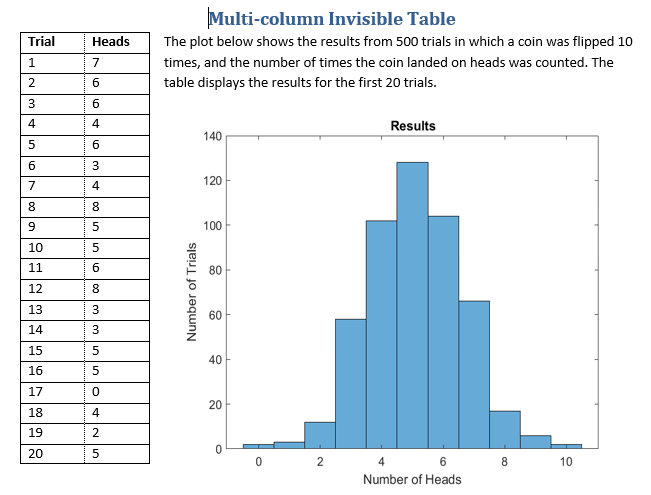

Import the DOM package so you do not have to use long, fully-qualified class names.

import mlreportgen.dom.*

Move to a new page in the existing document and add a heading to describe the table.

br = PageBreak();
append(rpt, br);
h = Heading(1, 'Multi-column Invisible Table');
h.Style = [h.Style {HAlign('center')}];
append(rpt, h);

Determine the styles for the different components on the page. The main table is invisible, so it does not have a border or separators.

mainTableStyle = {Width('100%'), Border('none') ColSep('none'), RowSep('none')};
dataTableStyle = {Border('solid'), ColSep('dotted'), RowSep('solid'),...
    OuterMargin('0pt', '0pt', '0pt', '0pt')};
dataTableEntriesStyle = {OuterMargin('0pt', '0pt', '0pt', '0pt'), VAlign('middle')};
histStyle = {InnerMargin('2pt', '2pt', '2pt', '2pt'), ...
    HAlign('center'), VAlign('bottom'), Width('5in'), Height('4in')};

Create example data representing 500 random coin flips. Then, create Text, FormalTable, and Image objects to display information about the data.

coinflips = randi(2, [500, 10]);
numHeads = sum(coinflips-1,2);

p = Text(['The plot below shows the results from 500 trials in which a coin was flipped 10 times, ',...
    'and the number of times the coin landed on heads was counted. ',...
    'The table displays the results for the first 20 trials.']);

dataHeader = {'Trial', 'Heads'};
dataBody = [(1:20)', numHeads(1:20)];
dataTable = FormalTable(dataHeader, dataBody);
dataTable.TableEntriesStyle = [dataTable.TableEntriesStyle dataTableEntriesStyle]; 
dataTable.Header.Style = [dataTable.Header.Style {Bold}];
dataTable.Style = [dataTable.Style dataTableStyle];

histogram(numHeads);
title('Results')
xlabel('Number of Heads')
ylabel('Number of Trials')
saveas(gcf,'histogram_img.png');
close(gcf)
h = Image('histogram_img.png');

Create the invisible table and begin adding components. Add the data table to the first row and specify that it spans two rows.

t = Table(2);
t.Style = [t.Style mainTableStyle];

row1 = TableRow;
row1.Style = [row1.Style {Width('100%')}];
entry1 = TableEntry;
append(entry1, dataTable);
entry1.RowSpan = 2;
entry1.Style = [entry1.Style {Width("40%")}];
append(row1, entry1);

Add the Text object to the first row as well and then append the row to the table.

entry2 = TableEntry(p);
entry2.Style = [entry2.Style {Width("60%")}];
append(row1, entry2);

append(t, row1);

Create a new row and add the histogram image as the only entry. The data table already fills the first columns of both the first and second rows, so the histogram will be placed in the second column.

row2 = TableRow;
entry3 = TableEntry;
h.Style = [h.Style histStyle];
append(entry3, h);
append(row2, entry3);
entry3.Style = [entry3.Style {Width('60%')}];

append(t,row2);

Generate and display the report.

append(rpt,t);
close(rpt);
rptview(rpt);

*Copyright 2018 The MathWorks, Inc.*